Project 8: Package Delivery Time Estimator (Linear + Data Table)

Delivery time (minutes) depends on distance (miles) with a linear model and includes a fixed handling time.

Tasks

1. Create a model T (d) = md + b using a chosen average speed and handling time.

2. Evaluate for d = 0 : 1 : 40.

3. Produce a table with columns: distance, time, and an interpretation column (short labels like “short”, “medium”, “long”).

4. Plot time vs distance and interpret slope and intercept

m = 2;   % Slope: It takes 2 minutes per mile (1/0.5)
b = 10;  % Intercept: 10 minutes for loading/unloading

d = (0:1:40)'; % Distance column vector from 0 to 40 miles

%% 2. Evaluate the Model
T = m*d + b; % Function for total delivery time in minutes

%% 3. Create Interpretation Labels
% We'll use categorical labels based on distance
labels = strings(size(d)); %Creates labels for short medium and long using the size of the d variable
labels(d < 10) = "Short"; %anything less than 10 is classified as short
labels(d >= 10 & d <= 25) = "Medium"; %anything classified 10 and greater but less than 25 is medium
labels(d > 25) = "Long"; %anything greater than 25 is considered long

% Produce the Table
DeliveryTable = table(d, T, labels, 'VariableNames', {'Distance_Miles', 'Time_Min', 'Category'}); %Creates a table following the table syntax
disp(head(DeliveryTable, 10)) % Display the first 10 rows

    Distance_Miles    Time_Min    Category
    ______________    ________    ________

          0              10       "Short" 
          1              12       "Short" 
          2              14       "Short" 
          3              16       "Short" 
          4              18       "Short" 
          5              20       "Short" 
          6              22       "Short" 
          7              24       "Short" 
          8              26       "Short" 
          9              28       "Short" 



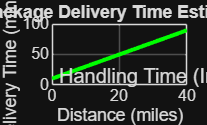


%% 4. Plot and Visualization
figure; 
plot(d, T, 'g-', 'LineWidth', 2); %plots the x and y axis with a line width of 2 
grid on; %allows for a grid 
xlabel('Distance (miles)'); %labels the x axis as distance
ylabel('Delivery Time (minutes)'); %labels y axis as delivery time
title('Package Delivery Time Estimator'); %creates a title for the table

% Annotate the graph to explain the model
text(2, b+5, ['Handling Time (Intercept) = ', num2str(b), ' min']); %Inputs a message of the handling time inside the graph